# Shinbrot Lorenz Targeting Replication

This consolidated Live Script contains three separated investigations:

1. Principal deterministic demonstration: Shinbrot bisection versus the corrected grid-first hybrid method. 2. Deterministic 60-source ensemble benchmark: the same two deterministic methods across a wider set of source states. 3. Gaussian-noise robustness investigation: the verified Shinbrot paper-aligned bisection method only.

The noise investigation is not a third deterministic targeting method and does not use the hybrid search.

clear; clc; close all;
rng(7);

## Lorenz System, Section, Target and Search Settings

The controlled Lorenz equations are

The perturbation pControl is a bounded parameter perturbation in the y-equation. In the deterministic searches it is held constant from the source section state through the requested targeting horizon.

verifiedBisectionIdentifier = verified_bisection_identifier();

params.sigma = 10;
params.rho = 28;
params.beta = 8/3;
params.zSection = 26.921;
params.xSectionMin = 8.0;
params.crossingDirection = +1;
params.odeOptions = odeset('RelTol', 1e-9, 'AbsTol', 1e-11);
params.eventDisableTime = 1e-6;
params.maxStepOffSection = 1e-5;
params.sectionTolerance = 1e-9;
params.maxTimeToNextValidSection = 100;
params.maxRejectedCrossings = 100;

target.x = 13.729;
target.state = [13.729; 19.585; params.zSection];
target.tolerance = 0.008;

control.deltaP = 0.1;
control.maxSearchCrossings = 12;
control.numParameterSamples = 81;
control.bisectionIterations = 24;
control.maxDiscontinuityIsolationDepth = 24;
control.maxDiscontinuityIntervals = 256;
control.searchMethod = 'hybridGridBisection';

benchmarkSettings.repetitions = 5;

sourceEnsembleSettings.candidateIndices = 100:300;
sourceEnsembleSettings.numSources = 60;
sourceEnsembleSettings.sourceSeparation = 1.5;
sourceEnsembleSettings.outputMatFile = 'shinbrot_source_ensemble.mat';
sourceEnsembleSettings.methodResultsCsv = ...
    'shinbrot_source_ensemble_method_results.csv';
sourceEnsembleSettings.pairedResultsCsv = ...
    'shinbrot_source_ensemble_paired_results.csv';
runExpensiveEnsemble = false;
runControlBoundSweep = false;

settingsTable = table( ...
    params.sigma, params.rho, params.beta, params.zSection, ...
    params.xSectionMin, target.x, target.tolerance, ...
    control.deltaP, control.maxSearchCrossings, ...
    control.numParameterSamples, control.bisectionIterations, ...
    string(verifiedBisectionIdentifier), ...
    'VariableNames', {'sigma', 'rho', 'beta', 'zSection', ...
    'xSectionMin', 'targetX', 'targetTolerance', 'DeltaP', ...
    'MaxSearchCrossings', 'ParameterSamples', ...
    'BisectionIterations', 'VerifiedBisectionIdentifier'});
disp(settingsTable);

    sigma    rho     beta     zSection    xSectionMin    targetX    targetTolerance    DeltaP    MaxSearchCrossings    ParameterSamples    BisectionIterations    VerifiedBisectionIdentifier
    _____    ___    ______    ________    ___________    _______    _______________    ______    __________________    ________________    ___________________    ___________________________

     10      28     2.6667     26.921          8         13.729          0.008          0.1              12                   81                   24              "shinbrotPaperBisection"  



## Paper Requirements Audit

The table separates statements made in Shinbrot, Ott, Grebogi and Yorke from implementation decisions and project-specific extensions. The deterministic hybrid method is retained only as a deterministic comparison; it is not part of the paper-mode noise experiment.

requirementsTable = table( ...
    ["Lorenz section"; ...
     "Control bound"; ...
     "Final bisection refinements"; ...
     "Discontinuity handling"; ...
     "Noise injection"; ...
     "Noise retargeting cadence"; ...
     "Noise realizations"; ...
     "Noise axis"; ...
     "Section-retarget mode"; ...
     "Hybrid grid-bisection"], ...
    ["Paper Lorenz example uses z = 26.921 and accepted side x > 8."; ...
     "Paper Lorenz example uses |delta p| <= 0.1."; ...
     "Paper note reports 24 refinements."; ...
     "Paper note 11 identifies discontinuities using crossing order."; ...
     "Paper states that random coordinate changes are made before each integration step."; ...
     "Paper states that the orbit is targeted again after every 40 integration steps."; ...
     "Paper noise plot uses ten realizations."; ...
     "Paper Figure 6 uses a normalized noise axis."; ...
     "Not stated as the paper protocol."; ...
     "Not stated as the paper method."], ...
    ["params.zSection = 26.921; params.xSectionMin = 8.0."; ...
     "control.deltaP = 0.1."; ...
     "control.bisectionIterations = 24 for the verified paper path."; ...
     "run_shinbrot_paper_bisection records crossing-order signatures."; ...
     "Fixed RK4 trials use currentState + sigmaNoise*randn(3,1) before each step."; ...
     "paperCycleCadenceRetargetMode sets retargetStepInterval = round(Tbar/dt), preserving the paper's about-one-map-cycle cadence while retaining dt = 0.001."; ...
     "Full paper-mode sweep uses sweep.numTrials = 10."; ...
     "Reported sigmaNoise is raw per-step coordinate standard deviation."; ...
     "Retained only as sectionRetargetMode, a project extension."; ...
     "Retained only as hybridGridBisection, a deterministic comparison."], ...
    ["implemented"; ...
     "implemented"; ...
     "implemented"; ...
     "paper-aligned reconstruction"; ...
     "implemented"; ...
     "cadence-matched reconstruction; literal paper40StepRetargetMode is preserved only for audit"; ...
     "implemented for the full sweep"; ...
     "labelled not directly comparable to Fig. 6"; ...
     "project-specific extension"; ...
     "project-specific extension"], ...
    ["none"; ...
     "none"; ...
     "none"; ...
     "label branch-order choices as reconstruction details"; ...
     "none"; ...
     "report Tbar, stepsPerMeanReturn, retargetStepInterval and cadenceRatio"; ...
     "do not overinterpret the coarse binomial fractions"; ...
     "do not claim quantitative equivalence to the paper axis"; ...
     "do not present as the paper noise protocol"; ...
     "do not present as the Shinbrot original method"], ...
    'VariableNames', {'Requirement', 'PaperEvidence', ...
    'CurrentImplementation', 'Status', 'RequiredAction'});
disp(requirementsTable);

             Requirement                                                PaperEvidence                                                                                                          CurrentImplementation                                                                                                                  Status                                                                             RequiredAction                             
    _____________________________    ____________________________________________________________________________________    __________________________________________________________________________________________________________________________________________________________    _____________________________________________________________________________________________    ______

## Nominal Return Map and Source State

The nominal uncontrolled map is generated with pControl = 0. Accepted points cross z = 26.921 in the positive direction and satisfy x > 8. The principal source is the complete three-dimensional state stored at the 150th accepted crossing; the scalar coordinate alone is not used to reconstruct the state.

fprintf('Generating the uncontrolled Poincare return map...\n');

Generating the uncontrolled Poincare return map...


X0 = [1; 1; 1];
numMapCrossings = 1200;
sourceIndex = 150;
mapData = generate_return_map(X0, numMapCrossings, params, 0);
if size(mapData.states, 2) < numMapCrossings
    error('Only %d valid section crossings were generated.', ...
        size(mapData.states, 2));
end

sourceState = mapData.states(:, sourceIndex);
if abs(sourceState(1) - target.x) <= target.tolerance
    error('The configured source point lies inside the target interval.');
end
sourceX = sourceState(1);

sourceSummary = table(sourceIndex, sourceX, target.x, ...
    abs(sourceX - target.x), numMapCrossings, ...
    'VariableNames', {'SourceIndex', 'SourceX', 'TargetX', ...
    'InitialScalarSeparation', 'GeneratedMapCrossings'});
disp(sourceSummary);

    SourceIndex    SourceX    TargetX    InitialScalarSeparation    GeneratedMapCrossings
    ___________    _______    _______    _______________________    _____________________

        150        12.807     13.729             0.92231                    1200         



## Principal Deterministic Demonstration

The deterministic comparison contains only two methods:

- shinbrotPaperBisection: the verified paper-aligned full-interval, crossing-order-aware bisection path.

- hybridGridBisection: the corrected grid-first method used only in the deterministic demonstration and deterministic ensemble benchmark.

The former generates candidate intervals through crossing-order-aware subdivision of the bounded parameter interval. The latter evaluates the complete 81-point grid at each horizon, verifies direct hits and adjacent brackets, then applies its own selection rule. These two search paths are deliberately distinct.

fprintf('Running the uncontrolled recurrence baseline...\n');

Running the uncontrolled recurrence baseline...


uncontrolled = uncontrolled_hitting_time_1d( ...
    sourceState, target, params, 2000);

fprintf('Running the verified Shinbrot bisection search...\n');

Running the verified Shinbrot bisection search...


bisectionControl = control;
bisectionControl.searchMethod = verifiedBisectionIdentifier;
bisectionSearch = search_parameter_to_target( ...
    sourceState, target, params, bisectionControl, ...
    verifiedBisectionIdentifier);
assert_verified_bisection_search( ...
    bisectionSearch, verifiedBisectionIdentifier, ...
    'principal deterministic bisection');
bisectionReplay = replay_parameter_live( ...
    sourceState, target, params, bisectionSearch);

fprintf('Running the deterministic grid-first hybrid search...\n');

Running the deterministic grid-first hybrid search...


hybridControl = control;
hybridControl.searchMethod = 'hybridGridBisection';
controlled = shinbrot_parameter_targeting( ...
    sourceState, target, params, hybridControl);
hybridSearch = controlled.search;
hybridReplay = result_to_replay_live(controlled, target);

bisectionDiagnostics = compact_search_diagnostics_live( ...
    'Shinbrot bisection', bisectionSearch, bisectionReplay);
hybridDiagnostics = compact_search_diagnostics_live( ...
    'Grid-first hybrid', hybridSearch, hybridReplay);
disp(bisectionDiagnostics);

        MethodLabel               SearchMethod          HitFound    ReplayHit    SelectedP    AbsoluteP    Horizon    FinalTargetError    ReplayTargetError    ParameterEvaluations    CrossingPropagations    GridEvaluations    FinalBracketBisectionIterations    TotalBisectionIterations    SingleRunSearchTime                               SelectionMethod                                FailureCode
    ____________________    ________________________    ________    _________    _________    _________    _______    ________________    _________________    <

disp(hybridDiagnostics);

        MethodLabel            SearchMethod         HitFound    ReplayHit    SelectedP    AbsoluteP    Horizon    FinalTargetError    ReplayTargetError    ParameterEvaluations    CrossingPropagations    GridEvaluations    FinalBracketBisectionIterations    TotalBisectionIterations    SingleRunSearchTime                       SelectionMethod                       FailureCode
    ___________________    _____________________    ________    _________    _________    _________    _______    ________________    _________________    __________________

## RMS Scale and Single-Source Timing Benchmark

The RMS calculation gives a scale for the y-equation perturbation. The formal single-source timing benchmark repeats each deterministic method five times and reports medians for search, replay and combined time.

fprintf('Computing the post-transient time-weighted RHS RMS...\n');

Computing the post-transient time-weighted RHS RMS...


rhsRms = compute_rhs_rms_live(mapData, params, control, 100);
disp(struct2table(rhsRms));

    rmsFx     rmsFy     rmsFz    transientCrossingIndex    transientTime    averagingDuration    maxParameterEffect    parameterToRmsFyRatio    paperApproximateRmsFy    rmsFyDifferenceFromPaperApproximation
    ______    ______    _____    ______________________    _____________    _________________    __________________    _____________________    _____________________    _____________________________________

    42.731    65.409    78.84             100                 161.28             1670.5                 0.1                  0.0015288                   100                            -34.591               




fprintf('Benchmarking the deterministic bisection and hybrid methods...\n');

Benchmarking the deterministic bisection and hybrid methods...


searchBenchmark = benchmark_shinbrot_search_methods( ...
    sourceState, target, params, control, benchmarkSettings);
disp(searchBenchmark.comparisonTable);

              Method              HitFound    SelectedP    Horizon    FinalError    ParameterEvaluations    CrossingPropagations    FinalBracketBisectionIterations    TotalBisectionIterations    GridEvaluations    MedianSearchTime    ControlledReplayCrossings    ReplayHit    MedianReplayTime    MedianSearchAndReplayTime                                SelectionMethod                                 FailureCode    FailureReason
    __________________________    ________    _________    _______    __________    ____________________    ____________________    _____

## Deterministic Sixty-Source Ensemble Benchmark

The 60-source ensemble is deterministic and retains both deterministic methods. Source indices are selected from 100:300 with `X_s - X_t` >= 1.5. The stored ensemble result is loaded only when it matches the current two-method settings.

if runExpensiveEnsemble
    fprintf('Running the sixty-source deterministic benchmark once...\n');
    sourceEnsemble = benchmark_shinbrot_source_ensemble( ...
        mapData, target, params, control, sourceEnsembleSettings);
elseif isfile(sourceEnsembleSettings.outputMatFile)
    savedEnsemble = load(sourceEnsembleSettings.outputMatFile);
    if is_valid_source_ensemble_live(savedEnsemble, target, control)
        fprintf('Loading the saved sixty-source deterministic benchmark...\n');
        sourceEnsemble = savedEnsemble;
    else
        warning(['Saved ensemble results are stale; no ensemble search ', ...
            'was run because runExpensiveEnsemble = false.']);
        sourceEnsemble = [];
    end
else
    warning(['No saved sixty-source benchmark found; no ensemble search ', ...
        'was run because runExpensiveEnsemble = false.']);
    sourceEnsemble = [];
end

Loading the saved sixty-source deterministic benchmark...



fprintf('\n========== Benchmark 1: Single-Source Median Timing ==========\n');


========== Benchmark 1: Single-Source Median Timing ==========


disp(searchBenchmark.comparisonTable);

              Method              HitFound    SelectedP    Horizon    FinalError    ParameterEvaluations    CrossingPropagations    FinalBracketBisectionIterations    TotalBisectionIterations    GridEvaluations    MedianSearchTime    ControlledReplayCrossings    ReplayHit    MedianReplayTime    MedianSearchAndReplayTime                                SelectionMethod                                 FailureCode    FailureReason
    __________________________    ________    _________    _______    __________    ____________________    ____________________    _____


========== Benchmark 2: Sixty-Source Method Summary ==========


              Method              NumberSources    NumberReplayHits    SuccessRate    MeanHorizon    MedianHorizon    MeanAbsoluteP    MedianAbsoluteP    MeanReplayTargetError    MedianReplayTargetError    MaximumReplayTargetError    MeanSearchTime    MedianSearchTime
    __________________________    _____________    ________________    ___________    ___________    _____________    _____________    _______________    _____________________    _______________________    ________________________    ______________    ________________

    {'shinbrotPaper


========== Full 120-Row Method Results ==========


    SourceIndex    SourceX              Method              HitFound    ReplayHit    SelectedP     AbsoluteP    Horizon    FinalTargetError    ReplayTargetError    ParameterEvaluations    CrossingPropagations    FinalBracketBisectionIterations    TotalBisectionIterations    GridEvaluations    SearchTime                                SelectionMethod                                 FailureCode    FailureReason    DiscontinuitiesDetected    DiscontinuityReductions    ContinuousIntervalsExamined    CrossingSignatureEvaluations    CertifiedParameterResolution    ParameterResolution


========== Benchmark 3: Sixty-Source Paired Summary ==========


    NumberSourcesTested    NumberShinbrotReplayHits    NumberHybridReplayHits    ShinbrotSuccessRate    HybridSuccessRate    NumberBothReplayHit    NumberSameSuccessfulHorizon    NumberDifferentSuccessfulHorizons    MatchedHybridSmaller    MatchedShinbrotSmaller    MatchedTies                                                                                          HybridSmallerSourceIndices                                                                                                  ShinbrotSmallerSourceIndices            TieSourceIndices    MeanShinbrotAbsoluteP    MedianShinbrotAbsoluteP    MeanHybridAbsoluteP    MedianHybridAbsoluteP    MeanAbsolutePDifference   


========== Full 60-Row Paired Results ==========


    SourceIndex    SourceX    ShinbrotHit    HybridHit    ShinbrotReplayHit    HybridReplayHit    ShinbrotP      HybridP      ShinbrotAbsoluteP    HybridAbsoluteP    AbsolutePDifference    ShinbrotHorizon    HybridHorizon    ShinbrotFinalTargetError    HybridFinalTargetError    ShinbrotReplayTargetError    HybridReplayTargetError    SameHorizon    BothReplayHit    SmallerMagnitudeMethod
    ___________    _______    ___________    _________    _________________    _______________    __________    __________    

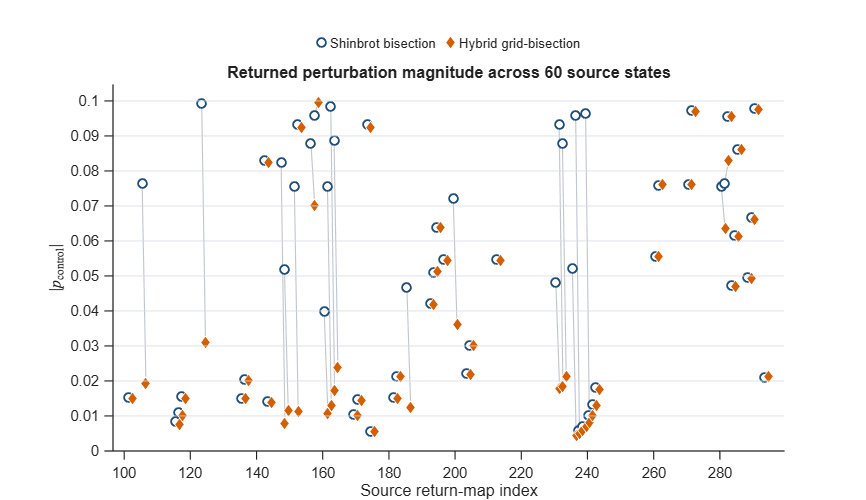

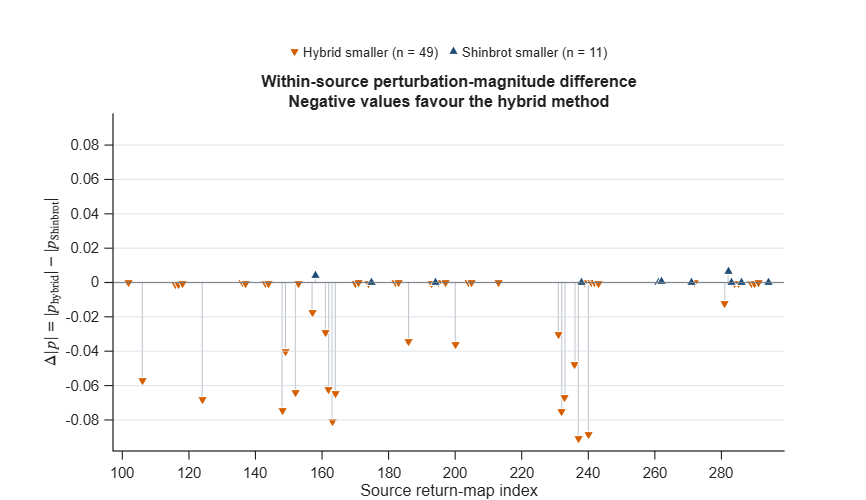

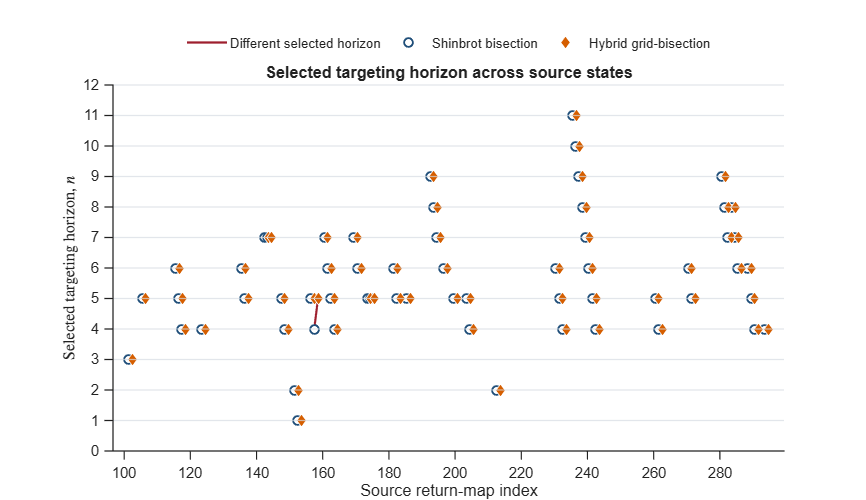

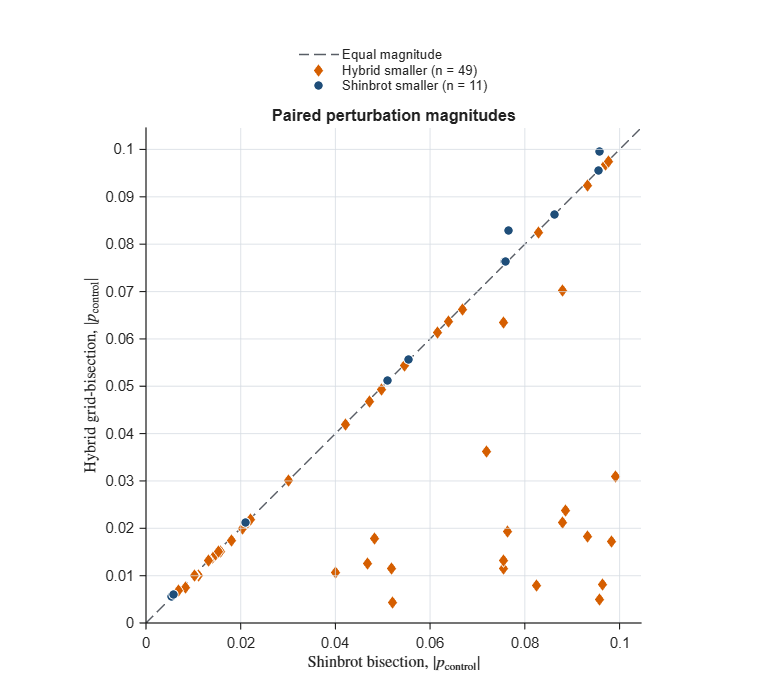


if ~isempty(sourceEnsemble)
    fprintf('\n========== Benchmark 2: Sixty-Source Method Summary ==========\n');
    disp(sourceEnsemble.methodSummary);

    fprintf('\n========== Full 120-Row Method Results ==========\n');
    disp(sourceEnsemble.methodResultsTable);

    fprintf('\n========== Benchmark 3: Sixty-Source Paired Summary ==========\n');
    disp(sourceEnsemble.summary);

    fprintf('\n========== Full 60-Row Paired Results ==========\n');
    disp(sourceEnsemble.pairedResultsTable);

    plot_shinbrot_source_ensemble(sourceEnsemble.pairedResultsTable);
end

## Deterministic Figures and Summary

These figures show the nominal attractor, scalar return map, uncontrolled recurrence, controlled hybrid replay, and the hybrid parameter-search landscape. The hybrid figures belong only to the deterministic comparison.

fprintf('\n========== Shinbrot Lorenz Targeting ==========\n');


========== Shinbrot Lorenz Targeting ==========


fprintf('Target X_t:                               %.6f\n', target.x);

Target X_t:                               13.729000


fprintf('Source index and X_s:                     %d, %.6f\n', ...
    sourceIndex, sourceX);

Source index and X_s:                     150, 12.806689


fprintf('Bisection selected p and horizon:          %.12g, %g\n', ...
    bisectionSearch.selectedP, bisectionSearch.horizon);

Bisection selected p and horizon:          0.0865456722677, 3


fprintf('Hybrid selected p and horizon:             %.12g, %g\n', ...
    controlled.selectedParameter, hybridSearch.horizon);

Hybrid selected p and horizon:             0.019375, 3


fprintf('Hybrid selection detail:                  %s\n', ...
    hybridSearch.selectionMethod);

Hybrid selection detail:                  grid-first verified adjacent-grid bracket bisection


fprintf('Hybrid grid evaluations:                  %g\n', ...
    hybridSearch.gridEvaluations);

Hybrid grid evaluations:                  243


fprintf('Bisection final target error:             %.12g\n', ...
    bisectionSearch.finalTargetError);

Bisection final target error:             4.06361699845e-09


fprintf('Hybrid final target error:                %.12g\n', ...
    hybridSearch.finalTargetError);

Hybrid final target error:                0.000563046852456


fprintf('Controlled/uncontrolled crossings:        %g / %g\n', ...
    controlled.numCrossings, uncontrolled.numCrossings);

Controlled/uncontrolled crossings:        3 / 266


fprintf('Time-weighted RMS (f_x, f_y, f_z):         %.6g, %.6g, %.6g\n', ...
    rhsRms.rmsFx, rhsRms.rmsFy, rhsRms.rmsFz);

Time-weighted RMS (f_x, f_y, f_z):         42.7314, 65.4089, 78.8398


fprintf('DeltaP / RMS f_y:                         %.6g\n', ...
    rhsRms.parameterToRmsFyRatio);

DeltaP / RMS f_y:                         0.00152884


fprintf('================================================\n');

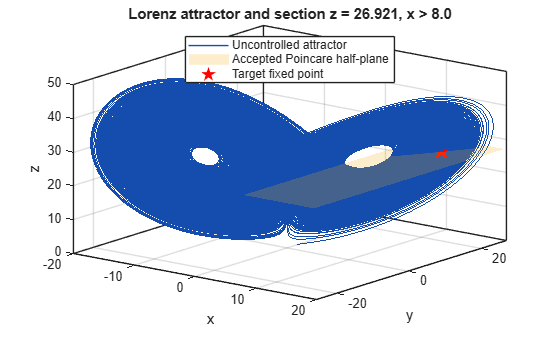

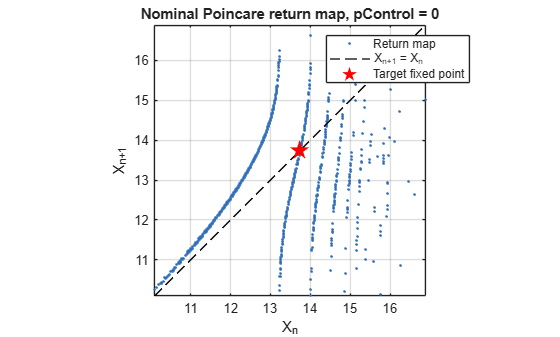

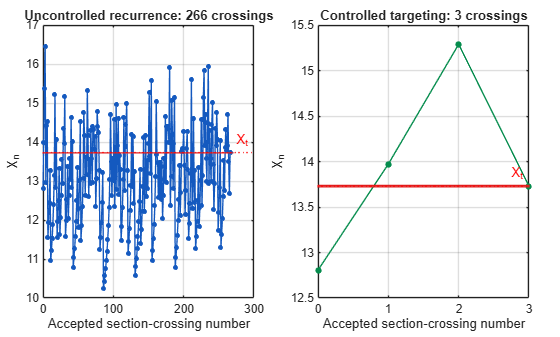

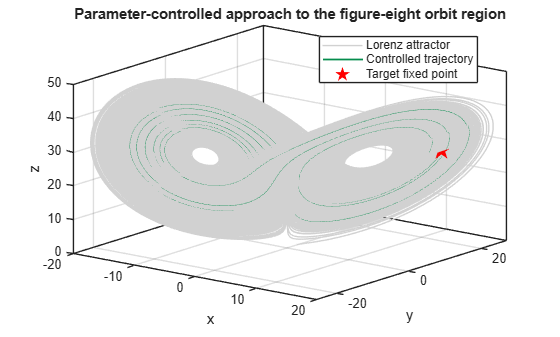

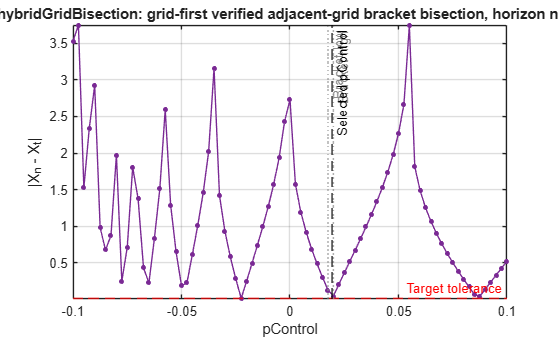


plot_shinbrot_results( ...
    mapData, uncontrolled, controlled, target, params, hybridControl);

## Robustness Investigation of the Bisection Method Under Gaussian Noise

This final investigation tests robustness of the verified Shinbrot bisection method only. It does not use the deterministic hybrid search. The purpose is to ask how the retained map-based targeting procedure behaves when the propagated Lorenz state is perturbed by independent Gaussian coordinate noise.

The implemented stochastic update is discrete. Before every fixed RK4 step, the current state is perturbed by

The RK4 step is then integrated from x_k^+. Thus sigma_noise is the per-step, per-coordinate standard deviation in Lorenz coordinate units. It has not been converted to the normalized noise measure used by Shinbrot et al.; this is therefore a qualitative noise-robustness replication and a quantitative assessment of this implementation.

Fixed-step RK4 is used because adaptive ode45 internal steps would make per-step noise ambiguous. Manual section detection interpolates between the actual integrated segment endpoints, stepStartState and stepEndState. Instantaneous jumps from x_k to x_k^+ are excluded from crossing detection.

The initial perturbation is obtained by calling search_parameter_to_target with the verified paper-bisection dispatcher identifier shinbrotPaperBisection. Shinbrot et al. state that retargeting was repeated after 40 integration steps and that this was typically about one map cycle, but the RK4 step size is not published. This reconstruction therefore retains dt = 0.001 and matches the cadence: the final mode paperCycleCadenceRetargetMode sets

For the present nominal map this is about 1519 RK4 steps, not 40. The literal paper40StepRetargetMode is preserved as historical audit code but is not used for the repaired final experiment. The decision state may be off the Poincare section; candidate forecasts are deterministic and begin from that full three-dimensional current state. Noise is applied only to the propagated plant trajectory.

The current pControl is held constant between consecutive retargeting step indices. If a retargeting search fails, the previous pControl is retained and the failure is counted.

The active sweep configuration is

The noise investigation considers sigma_noise in {0, 0.01, 0.03, 0.05, 0.075, 0.1, 0.15, 0.2, 0.3, 0.5, 1.0}, with ten independent realizations at each level. This is ten nonzero noise levels plus the zero-noise reference level.

The total trial count is calculated from the executable configuration. Each trial has a reproducible seed

Saved results are accepted only if field-by-field configuration validation passes, the result is complete, every trial uses the verified paper-bisection identifier, and no hybrid provenance is present. The full 110-trial sweep is not launched automatically by this Live Script. If no validated full result exists, the deterministic investigations remain complete and the workflow reports the validation status.

========== Paper-Cycle Bisection Noisy Shinbrot Lorenz Targeting ==========
Loading or generating deterministic source state X_150...
Source X_s = 12.8066889599, target X_t = 13.729
Mean return time Tbar = 1.51859, steps per mean return = 1518.6, cycle-matched interval = 1519 steps, cadence ratio = 1.00027
Literal 40-step time at dt = 0.001 is 0.04, cadence ratio 0.0263402; that is about 38.0x too frequent.
Computed full-trial RK4-step budget = 227789 (safety factor 2.5).
Finding initial deterministic bisection perturbation...
Initial pControl = 0.0865456722677, horizon = 3
Loaded valid cached zero-noise validation from noise_validation_paper_cycle_retarget_11sigma.mat.

Experiment type: FULL NOISE SWEEP
Maximum accepted crossings per trial: 60
Global RK4-step budget per trial: 227789
Noise levels: 11
Trials per level: 10
Total trials: 110
Retargeting mode: paperCycleCadenceRetargetMode
Retarget step interval: 1519
Cadence ratio: 1.00027
Available process workers: 8
Requested workers: 

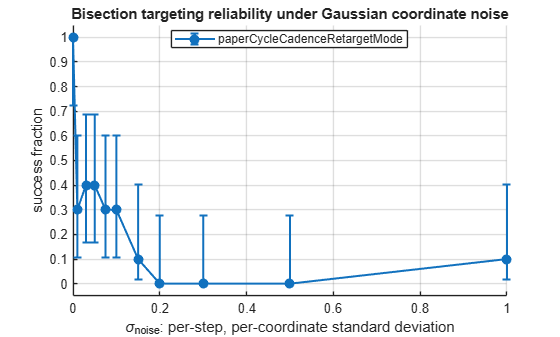

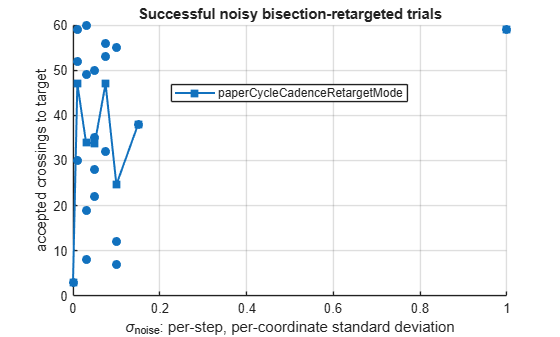

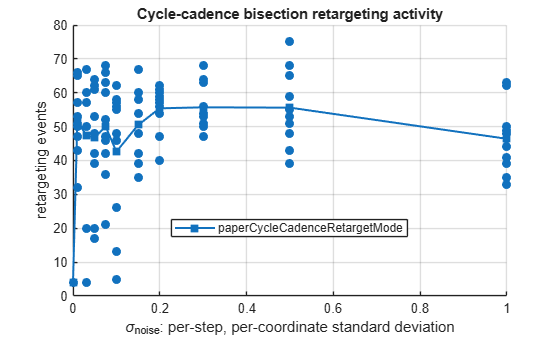

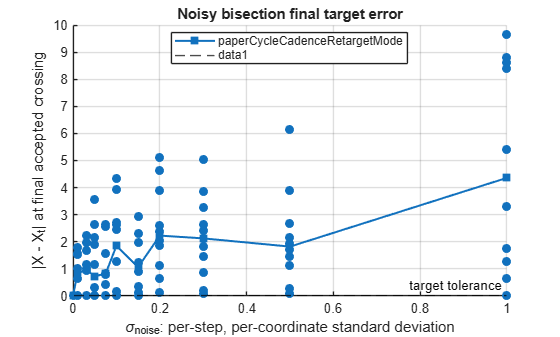

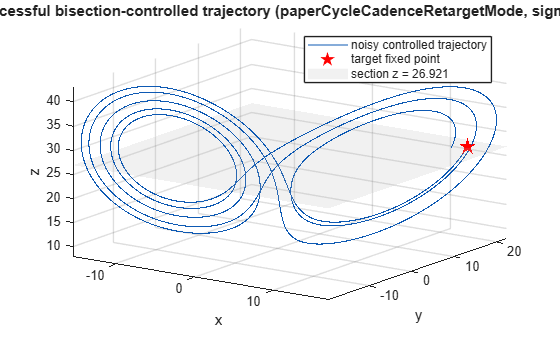

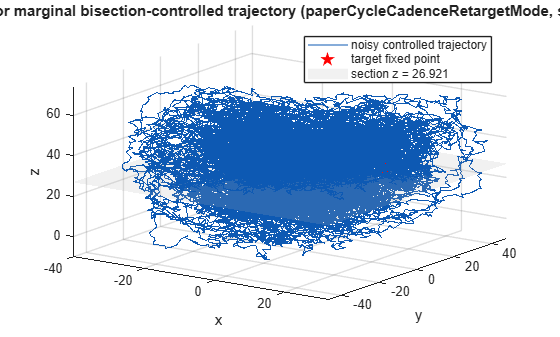

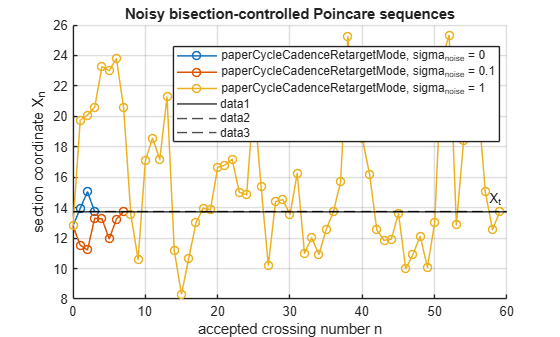

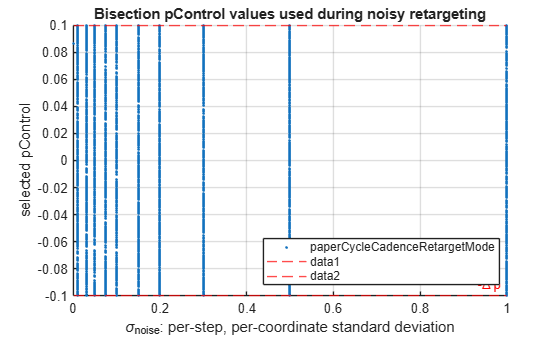

Noise plots use per-step, per-coordinate Gaussian standard deviation and fixed RK4 step dt = 0.001.
Directly comparable to Shinbrot Fig. 6 axis: false
Verified bisection identifier: shinbrotPaperBisection
Noise retargeting mode: paperCycleCadenceRetargetMode
Total configured trials: 110
Result completed: true
Directly comparable to Shinbrot Fig. 6 axis: false


noiseAction = 'resumeFull';
% Permitted values:
%   'skip'           omit this section without error
%   'validate'       run deterministic and zero-noise validation only
%   'loadFull'       load a complete, configuration-matched full result
%   'pilot'          run trial 1 at each sigma into the final checkpoint
%   'resumeFull'     resume the remaining final trials from checkpoint
%   'regenerateFull' explicit full-run alias; also resumes checkpoint
validNoiseActions = {'skip', 'validate', 'loadFull', ...
    'pilot', 'resumeFull', 'regenerateFull'};
if ~any(strcmp(noiseAction, validNoiseActions))
    error('Unknown noiseAction: %s', noiseAction);
end

noiseWorkflow = main_shinbrot_noise_demo(noiseAction);


if isstruct(noiseWorkflow) && isfield(noiseWorkflow, 'validation') && ...
        isfield(noiseWorkflow.validation, 'sweep')
    validationSummary = table( ...
        string(noiseWorkflow.noiseAction), ...
        noiseWorkflow.readyForFullSweep, ...
        noiseWorkflow.validation.noise.maxControlledCrossings, ...
        noiseWorkflow.validation.noise.maxRk4Steps, ...
        numel(noiseWorkflow.validation.sweep.sigmaNoiseValues), ...
        noiseWorkflow.validation.sweep.numTrials, ...
        noiseWorkflow.validation.currentConfig.totalTrials, ...
        noiseWorkflow.validation.parallel.availableWorkers, ...
        noiseWorkflow.validation.parallel.selectedWorkers, ...
        noiseWorkflow.validation.cadence.Tbar, ...
        noiseWorkflow.validation.cadence.stepsPerMeanReturn, ...
        noiseWorkflow.validation.cadence.cadenceRatio, ...
        noiseWorkflow.validation.runtimeEstimate.serialSeconds, ...
        noiseWorkflow.validation.runtimeEstimate.parallelSeconds, ...
        'VariableNames', {'NoiseAction', 'ReadyForFullSweep', ...
        'MaxAcceptedCrossings', 'MaxRk4Steps', 'NoiseLevels', ...
        'TrialsPerLevel', 'TotalTrials', 'AvailableWorkers', ...
        'SelectedWorkers', 'MeanReturnTime', 'StepsPerMeanReturn', ...
        'CadenceRatio', 'EstimatedSerialSeconds', ...
        'EstimatedParallelSeconds'});
    disp(validationSummary);
end

    NoiseAction     ReadyForFullSweep    MaxAcceptedCrossings    MaxRk4Steps    NoiseLevels    TrialsPerLevel    TotalTrials    AvailableWorkers    SelectedWorkers    MeanReturnTime    StepsPerMeanReturn    CadenceRatio    EstimatedSerialSeconds    EstimatedParallelSeconds
    ____________    _________________    ____________________    ___________    ___________    ______________    ___________    ________________    _______________    ______________    __________________    ____________    ______________________    __________


if isstruct(noiseWorkflow) && isfield(noiseWorkflow, 'noiseResults') && ...
        ~isempty(noiseWorkflow.noiseResults)
    fprintf('\nFull paper-mode noise results were loaded or regenerated above.\n');
else
    fprintf(['\nFull paper-mode noise results are unavailable; no ', ...
        'Monte Carlo noise sweep has been displayed.\n']);
end


Full paper-mode noise results were loaded or regenerated above.


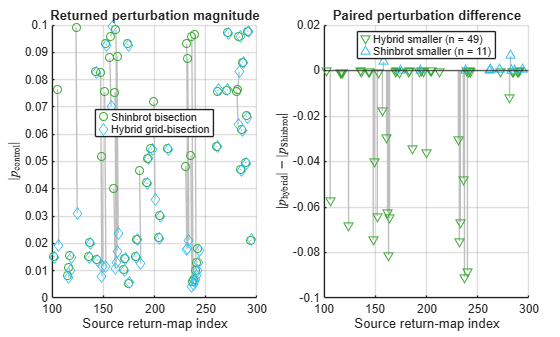

Unrecognized function or variable 'outputDirectory'.


%% Ensemble perturbation diagnostics: first two plots side by side

pairedResultsTable = sourceEnsemble.pairedResultsTable;

[sourceIndex, order] = sort(pairedResultsTable.SourceIndex(:));
paired = pairedResultsTable(order, :);

shinbrotVerified = logical(paired.ShinbrotReplayHit);
hybridVerified   = logical(paired.HybridReplayHit);
bothVerified     = logical(paired.BothReplayHit);

shinbrotMagnitude = paired.ShinbrotAbsoluteP;
hybridMagnitude   = paired.HybridAbsoluteP;
pairedDifference  = paired.AbsolutePDifference;

shinbrotHorizon = paired.ShinbrotHorizon;
hybridHorizon   = paired.HybridHorizon;

sourceRange = max(sourceIndex) - min(sourceIndex);
sourceOffset = max(0.25, 0.003 * sourceRange);

combinedFigure = figure('Name', 'Ensemble perturbation diagnostics', ...
    'NumberTitle', 'off');

tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

%% Panel 1: returned perturbation magnitudes
nexttile;
hold on;

pairMask = bothVerified & isfinite(shinbrotMagnitude) & isfinite(hybridMagnitude);

for row = find(pairMask).'
    plot(sourceIndex(row) + [-sourceOffset, sourceOffset], ...
        [shinbrotMagnitude(row), hybridMagnitude(row)], '-', ...
        'Color', [0.75 0.75 0.75], ...
        'HandleVisibility', 'off');
end

shinbrotMask = shinbrotVerified & isfinite(shinbrotMagnitude);
hybridMask   = hybridVerified & isfinite(hybridMagnitude);

plot(sourceIndex(shinbrotMask) - sourceOffset, ...
    shinbrotMagnitude(shinbrotMask), 'o', ...
    'LineStyle', 'none', ...
    'DisplayName', 'Shinbrot bisection');

plot(sourceIndex(hybridMask) + sourceOffset, ...
    hybridMagnitude(hybridMask), 'd', ...
    'LineStyle', 'none', ...
    'DisplayName', 'Hybrid grid-bisection');

xlabel('Source return-map index');
ylabel('$|p_{\mathrm{control}}|$', 'Interpreter', 'latex');
title('Returned perturbation magnitude');
legend('Location', 'best');
grid on;

%% Panel 2: paired perturbation difference
nexttile;
hold on;

comparisonMask = bothVerified & isfinite(pairedDifference);
negativeMask = comparisonMask & pairedDifference < 0;
positiveMask = comparisonMask & pairedDifference > 0;
equalMask    = comparisonMask & pairedDifference == 0;

yline(0, '-', 'HandleVisibility', 'off');

for row = find(comparisonMask).'
    plot([sourceIndex(row), sourceIndex(row)], ...
        [0, pairedDifference(row)], '-', ...
        'Color', [0.75 0.75 0.75], ...
        'HandleVisibility', 'off');
end

plot(sourceIndex(negativeMask), pairedDifference(negativeMask), 'v', ...
    'LineStyle', 'none', ...
    'DisplayName', sprintf('Hybrid smaller (n = %d)', sum(negativeMask)));

plot(sourceIndex(positiveMask), pairedDifference(positiveMask), '^', ...
    'LineStyle', 'none', ...
    'DisplayName', sprintf('Shinbrot smaller (n = %d)', sum(positiveMask)));

plot(sourceIndex(equalMask), pairedDifference(equalMask), 'o', ...
    'LineStyle', 'none', ...
    'DisplayName', sprintf('Equal magnitude (n = %d)', sum(equalMask)));

xlabel('Source return-map index');
ylabel('$|p_{\mathrm{hybrid}}|-|p_{\mathrm{Shinbrot}}|$', ...
    'Interpreter', 'latex');
title('Paired perturbation difference');
legend('Location', 'best');
grid on;

## Scaling in the Control Bound

The original paper reports the scaling law

where s is the fitted slope of mean targeting horizon against log10(Delta p). This section is separate from the deterministic bisection/hybrid comparison and from the noise-robustness study. It uses only the verified paper-bisection method.

The historical file shinbrot_control_bound_sweep.mat is preserved but is not used as repaired evidence. The repaired result is saved separately with a configuration and dependency fingerprint.

controlBoundFile = 'shinbrot_control_bound_sweep_paper_bisection.mat';
historicalControlBoundFile = 'shinbrot_control_bound_sweep.mat';
controlBoundOptions.deltaPValues = logspace(-2, 0, 9);
controlBoundOptions.numSources = 25;
controlBoundOptions.randomSeed = 20260814;
controlBoundOptions.sourceSeparation = 1.5;
controlBoundOptions.candidateRange = 100:300;
controlBoundOptions.horizonCap = 25;
controlBoundOptions.saveMatFile = controlBoundFile;
controlBoundOptions.verbose = true;

controlBoundResults = [];
if runControlBoundSweep
    fprintf('Running the repaired paper-bisection control-bound sweep once...\n');
    controlBoundResults = shinbrot_control_bound_sweep( ...
        mapData, controlBoundOptions);
elseif isfile(controlBoundFile)
    savedControlBound = load(controlBoundFile, 'results');
    if isfield(savedControlBound, 'results') && ...
            is_valid_control_bound_result_live(savedControlBound.results, ...
            controlBoundOptions, target, params)
        fprintf('Loading repaired paper-bisection control-bound result from %s.\n', ...
            controlBoundFile);
        controlBoundResults = savedControlBound.results;
    else
        warning(['Saved repaired control-bound result is stale or invalid; ', ...
            'no control-bound sweep was run because runControlBoundSweep = false.']);
    end
else
    warning(['No repaired paper-bisection control-bound result was found. ', ...
        'Historical file %s is preserved but not plotted as repaired evidence. ', ...
        'Set runControlBoundSweep = true to generate %s.'], ...
        historicalControlBoundFile, controlBoundFile);
end

if ~isempty(controlBoundResults)
    disp(controlBoundResults.levels);
    fprintf('Control-bound fitted slope: %.6g\n', ...
        controlBoundResults.fit.slope);
    fprintf('lambda_fit = ln(10)/|s|: %.6g\n', ...
        controlBoundResults.fit.lambdaFromSlope);
    fprintf('Return-map lambda: %.6g\n', ...
        controlBoundResults.returnMapLambda);
    plot_shinbrot_control_bound_results(controlBoundResults);
end

## Local Helper Functions

function rhsRms = compute_rhs_rms_live( ...
    mapData, params, control, transientCrossingIndex)
if transientCrossingIndex < 1 || ...
        transientCrossingIndex > numel(mapData.eventTimes)
    error('Transient crossing index %d is unavailable.', ...
        transientCrossingIndex);
end
transientTime = mapData.eventTimes(transientCrossingIndex);
keep = mapData.t >= transientTime;
t = mapData.t(keep);
X = mapData.X(keep, :);
if numel(t) < 2
    error('At least two post-transient samples are required for RMS.');
end
duration = t(end) - t(1);
if ~isfinite(duration) || duration <= 0
    error('RMS averaging duration must be finite and positive.');
end
F = NaN(size(X));
for i = 1:size(X, 1)
    F(i, :) = lorenz_rhs(t(i), X(i, :).', params, 0).';
end
rhsRms.rmsFx = sqrt(trapz(t, F(:, 1).^2) / duration);
rhsRms.rmsFy = sqrt(trapz(t, F(:, 2).^2) / duration);
rhsRms.rmsFz = sqrt(trapz(t, F(:, 3).^2) / duration);
rhsRms.transientCrossingIndex = transientCrossingIndex;
rhsRms.transientTime = transientTime;
rhsRms.averagingDuration = duration;
rhsRms.maxParameterEffect = control.deltaP;
rhsRms.parameterToRmsFyRatio = control.deltaP / rhsRms.rmsFy;
rhsRms.paperApproximateRmsFy = 100;
rhsRms.rmsFyDifferenceFromPaperApproximation = ...
    rhsRms.rmsFy - rhsRms.paperApproximateRmsFy;
end

function replay = replay_parameter_live(sourceState, target, params, search)
replay.hit = false;
replay.numCrossings = Inf;
replay.physicalTime = Inf;
replay.targetError = Inf;
replay.failed = false;
replay.t = [];
replay.X = [];
replay.states = [];
replay.xSequence = sourceState(1);
if ~search.found || ~isfinite(search.selectedP) || ...
        ~isfinite(search.horizon)
    replay.failed = true;
    return;
end
currentState = sourceState(:);
currentTime = 0;
tFull = [];
XFull = [];
states = NaN(3, search.horizon);
for crossing = 1:search.horizon
    segment = next_valid_section_crossing( ...
        currentState, params, search.selectedP);
    if ~segment.success
        replay.failed = true;
        replay.numCrossings = crossing - 1;
        return;
    end
    [tFull, XFull] = append_segment_live( ...
        tFull, XFull, currentTime, segment);
    currentTime = currentTime + segment.eventTime;
    currentState = segment.eventState;
    states(:, crossing) = currentState;
end
replay.numCrossings = search.horizon;
replay.physicalTime = currentTime;
replay.targetError = abs(currentState(1) - target.x);
replay.hit = replay.targetError <= target.tolerance;
replay.t = tFull;
replay.X = XFull;
replay.states = states;
replay.xSequence = [sourceState(1), states(1, :)];
end

function replay = result_to_replay_live(result, target)
replay.hit = result.hit;
replay.numCrossings = result.numCrossings;
replay.physicalTime = result.physicalTime;
replay.failed = ~result.hit;
if isempty(result.states)
    replay.targetError = Inf;
else
    replay.targetError = abs(result.states(1, end) - target.x);
end
replay.t = result.t;
replay.X = result.X;
replay.states = result.states;
replay.xSequence = result.xSequence;
end

function diagnostics = compact_search_diagnostics_live(label, search, replay)
MethodLabel = string(label);
SearchMethod = string(search.method);
HitFound = search.found;
ReplayHit = replay.hit;
SelectedP = search.selectedP;
AbsoluteP = abs(search.selectedP);
Horizon = search.horizon;
FinalTargetError = search.finalTargetError;
ReplayTargetError = replay.targetError;
ParameterEvaluations = search.parameterEvaluations;
CrossingPropagations = search.crossingPropagations;
GridEvaluations = search.gridEvaluations;
FinalBracketBisectionIterations = ...
    search.finalBracketBisectionIterations;
TotalBisectionIterations = search.totalBisectionIterations;
SingleRunSearchTime = search.searchTime;
SelectionMethod = string(search.selectionMethod);
FailureCode = string(search.failureCode);
diagnostics = table(MethodLabel, SearchMethod, HitFound, ReplayHit, ...
    SelectedP, AbsoluteP, Horizon, FinalTargetError, ...
    ReplayTargetError, ParameterEvaluations, CrossingPropagations, ...
    GridEvaluations, FinalBracketBisectionIterations, ...
    TotalBisectionIterations, SingleRunSearchTime, SelectionMethod, ...
    FailureCode);
end

function [tFull, XFull] = append_segment_live( ...
    tFull, XFull, currentTime, segment)
tSegment = currentTime + segment.t;
if isempty(tFull)
    tFull = tSegment;
    XFull = segment.X;
else
    tFull = [tFull; tSegment(2:end)];
    XFull = [XFull; segment.X(2:end, :)];
end
end

function valid = is_valid_source_ensemble_live(saved, target, control)
required = {'sourceIndices', 'methodResultsTable', ...
    'pairedResultsTable', 'summary', 'methodSummary', ...
    'studySettings', 'target', 'control'};
valid = all(isfield(saved, required));
if ~valid
    return;
end
methods = saved.methodResultsTable.Method;
methodVariables = saved.methodResultsTable.Properties.VariableNames;
pairedVariables = saved.pairedResultsTable.Properties.VariableNames;
valid = istable(saved.methodResultsTable) && ...
    istable(saved.pairedResultsTable) && istable(saved.summary) && ...
    istable(saved.methodSummary) && ...
    numel(saved.sourceIndices) == 60 && ...
    numel(unique(saved.sourceIndices)) == 60 && ...
    all(saved.sourceIndices >= 100 & saved.sourceIndices <= 300) && ...
    height(saved.methodResultsTable) == 120 && ...
    height(saved.pairedResultsTable) == 60 && ...
    sum(strcmp(methods, verified_bisection_identifier())) == 60 && ...
    sum(strcmp(methods, 'hybridGridBisection')) == 60 && ...
    all(saved.methodResultsTable.GridEvaluations(strcmp(methods, ...
        verified_bisection_identifier())) == 0) && ...
    all(ismember({'FailureCode', 'FailureReason'}, methodVariables)) && ...
    all(ismember({'ShinbrotFinalTargetError', ...
        'HybridFinalTargetError', 'ShinbrotReplayTargetError', ...
        'HybridReplayTargetError'}, pairedVariables)) && ...
    saved.studySettings.numSources == 60 && ...
    saved.studySettings.sourceSeparation == 1.5 && ...
    isequal(saved.studySettings.candidateIndices(:).', 100:300) && ...
    saved.control.maxSearchCrossings == control.maxSearchCrossings && ...
    saved.control.deltaP == control.deltaP && ...
    saved.target.x == target.x && ...
    saved.target.tolerance == target.tolerance;
end

function valid = is_valid_control_bound_result_live( ...
    results, options, target, params)
valid = false;
required = {'levels', 'trials', 'configuration', ...
    'verifiedBisectionIdentifier', 'fit', 'published', ...
    'returnMapLambda', 'returnMapImpliedSlope'};
if ~isstruct(results) || ~all(isfield(results, required))
    return;
end
if ~strcmp(results.verifiedBisectionIdentifier, verified_bisection_identifier())
    return;
end
if ~istable(results.trials) || ...
        ~any(strcmp(results.trials.Properties.VariableNames, 'searchMethod')) || ...
        ~all(strcmp(results.trials.searchMethod, verified_bisection_identifier()))
    return;
end
config = results.configuration;
configRequired = {'signatureText', 'deltaPValues', 'sourceIndices', ...
    'randomSeed', 'horizonCap', 'targetX', 'targetTolerance', ...
    'sigma', 'rho', 'beta', 'zSection', 'xSectionMin'};
if ~isstruct(config) || ~all(isfield(config, configRequired))
    return;
end
valid = isequal(config.deltaPValues(:).', options.deltaPValues(:).') && ...
    config.randomSeed == options.randomSeed && ...
    config.horizonCap == options.horizonCap && ...
    config.targetX == target.x && ...
    config.targetTolerance == target.tolerance && ...
    config.sigma == params.sigma && ...
    config.rho == params.rho && ...
    config.beta == params.beta && ...
    config.zSection == params.zSection && ...
    config.xSectionMin == params.xSectionMin;
end